**Wiadomości:**

- **rozkład t-Studenta,**

- **poziom istotności** (**α**) – przyjęte z góry dopuszczalne ryzyko popełnienia [błędu I rodzaju](https://pl.wikipedia.org/wiki/B%C5%82%C4%85d_pierwszego_rodzaju) (uznania prawdziwej hipotezy zerowej za fałszywą).

## **Korelacja liniowa r-Pearsona**

**-wspólczynnik korelacji **

[Korelacja liniowa](https://pl.wikipedia.org/wiki/Wsp%C3%B3%C5%82czynnik_korelacji_Pearsona) to podstawowa miara określająca  występowanie (lub brak występowania) zwiazku między parametrami $x_i$ oraz $y_i$

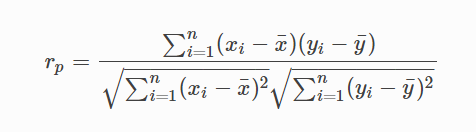

przy czym:


$$-1\le r_p \le 1$$


Informacja:

- $r_p$ > 0 korelacja dodatnia– gdy wartość X rośnie to Y też

- $r_p$= 0 brak korelacji– gdy X rośnie to Y czasem rośnie a czasem maleje

- $r_p$ < 0 korelacja ujemna– gdy X rośnie to Y maleje

"Siła korelacji":

- $\left|r_p \right|$<0,20 – brak związku liniowego

- 0,20≤$\left|r_p \right|$<0,40 – słaba zależność

- 0,4≤$\left|r_p \right|$<0,70– umiarkowana zależność

- 0,70≤$\left|r_p \right|$<0,90 – dość silna zależność

- $\left|r_p \right|$≥0,9 – bardzo silna zależność

Przykład

- Utworzenie pliku auto.xslx

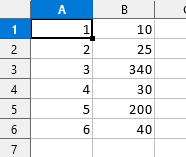

Pobranie danych z pliku auto.xslx

Zasosowanie funkcji  [**readcell**](https://www.mathworks.com/help/releases/R2020a/matlab/ref/readcell.html) 

%clear all; close all; clc; clearvars
%dodatkowe funkcje
opts = detectImportOptions('auto.xlsx');
preview('auto.xlsx',opts)

ans = 6×2 table
    Var1    Var2
    ____    ____

     1       10 
     2       25 
     3      340 
     4       30 
     5      200 
     6       40 


%załadowanie danych
C = readcell('auto.xlsx','Range','A1:B6')

C = 6×2 cell array
    {[1]}    {[ 10]}
    {[2]}    {[ 25]}
    {[3]}    {[340]}
    {[4]}    {[ 30]}
    {[5]}    {[200]}
    {[6]}    {[ 40]}


Zasosowanie funkcji [**corrcoef**](https://www.mathworks.com/help/releases/R2020a/matlab/ref/corrcoef.html)

rp1=corrcoef(cell2mat(C))

rp1 =     1.0000    0.1458
    0.1458    1.0000


Brak związku liniowego rp1=0,1458

Lub import z pliku auto2.xslx

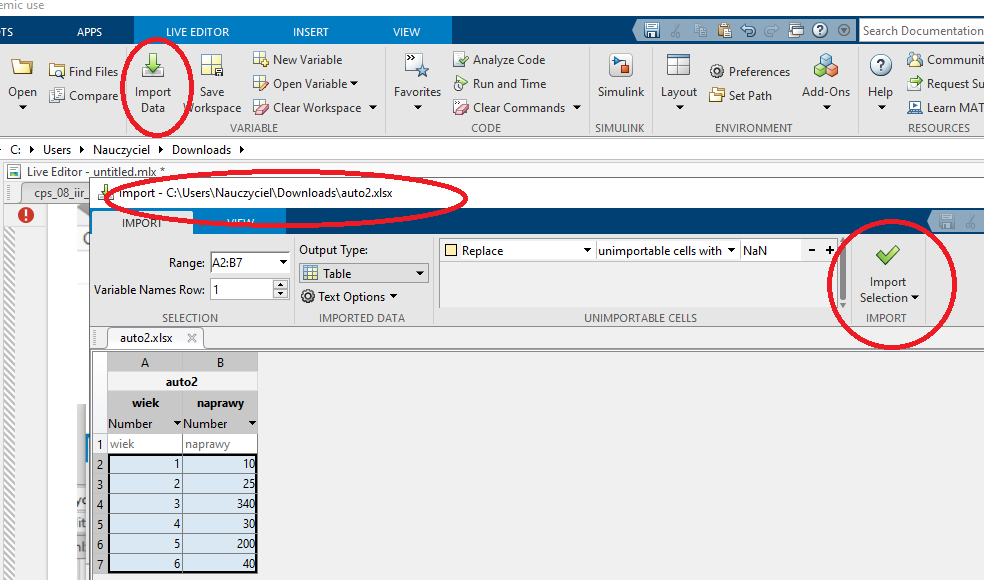

Import z pliku 

%rp1b=corrcoef(auto2.wiek,auto2.naprawy)

lub gdy zaimportujemu (narzędziem Home / Import Data) dane z pliku auto.xslx

%rp2c=corrcoef(auto.VarName1,auto.VarName2)

przykład 2  - plik chemia.xslx

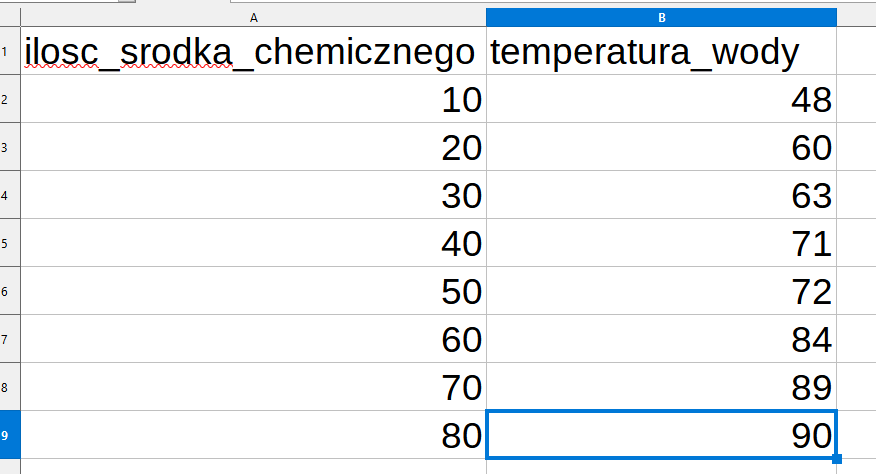

%opts = detectImportOptions('C:\Users\Nauczyciel\Downloads\chemia.xlsx');
opts = detectImportOptions('chemia.xlsx');
preview('chemia.xlsx',opts)

ans = 8×3 table
    ilosc_srodka_chemicznego    Var2    temperatura_wody
    ________________________    ____    ________________

               10                48        {0×0 char}   
               20                60        {0×0 char}   
               30                63        {0×0 char}   
               40                71        {0×0 char}   
               50                72        {0×0 char}   
               60                84        {0×0 char}   
               70                89        {0×0 char}   
               80                90        {0×0 char}   


C2 = readcell('chemia.xlsx','Range','A2:B9')

C2 = 8×2 cell array
    {[10]}    {[48]}
    {[20]}    {[60]}
    {[30]}    {[63]}
    {[40]}    {[71]}
    {[50]}    {[72]}
    {[60]}    {[84]}
    {[70]}    {[89]}
    {[80]}    {[90]}


obliczamy korelacje

rp2=corrcoef(cell2mat(C2))

rp2 =     1.0000    0.9829
    0.9829    1.0000


Bardzo silna zależność liniowa rp2=0,9829

## Testowanie istotności statystycznej współczynnika korelacji liniower r-Pearsona

Aby określić czy wyznaczony współczynnik korelacji jest istotny statystycznie konieczne jest postawienie hipotezy zerowej H0:

H0 - nie istnieje korelacja pomiędzy parametrami

H1- hipoteza alternatywna

Zakłada się, że statystyka przyjmuje rozkład **t-Studenta** o k=n−2 stopniach swobody i dla współczynnika korelacji liniowej Pearsona $r_p$ wartość statystyki wynosi

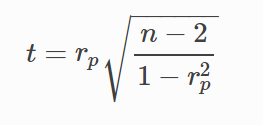

gdzie: n>2, $r_p \not= -1$lub $r_p \not= 1$

Wyznaczoną na jej podstawie wartość p (z rozkładu t-Studenta) porównywana jest z założonym poziomem istotności α (alpha)

- jeżeli p≤α to odrzucamy H0 przyjmując H1

- jeżeli p>α to nie ma podstaw do odrzucenia H0

p = 0.95;   
alpha=1-p %0,05 %założony poziom istotności

alpha = 0.0500


k1=size(C,1)-2 % 6-2 =4 liczba stopni swobody

k1 = 4

%statystyka testowa
tp1=rp1(1,2)*sqrt((k1)/(1-rp1(1,2)^2))

tp1 = 0.2948


pLo = alpha/2

pLo = 0.0250

pUp = 1 - alpha/2

pUp = 0.9750

%użycie funkcji (tinv) odwrotności dystrybuanty rozkładu t-Student
crit1 = tinv([pLo pUp], k1) %obliczamy obustronnie przedziały krytyczne

crit1 =    -2.7764    2.7764


ponieważ obszar krytyczny $\left(-\infty ,-2,7764>\cup <2,7764,+\right.$$\infty$) to statystyka testowa t1=0,2948 nie należy do obszaru krytycznego,  nie ma więc podstaw do odrzucenia hipotezy H0 (nie istniej korelacja). Sprawdzamy prawdopodobiestwa:

pt1=2*(tcdf(-tp1,k1))

pt1 = 0.7828

co odpowiada

pt1=2*(1-tcdf(tp1,k1))

pt1 = 0.7828

pt1=0,7828>alpha=0,05  (jeżeli p>α to nie ma podstaw do odrzucenia H0 - nie istnieje korelacja pomiędzy parametrami).

**Przykład - zestaw danych 2 (z 'chemia.xlsx')**

k2=size(cell2mat(C2),1)-2 %k2=6

k2 = 6

p = 0.95;   
alpha=1-p %poziom istotności alpha=0,05

alpha = 0.0500

%statystyka testowa
tp2=rp2(1,2)*sqrt((k2)/(1-rp2(1,2)^2))

tp2 = 13.0734


pLo = alpha/2

pLo = 0.0250

pUp = 1 - alpha/2

pUp = 0.9750

crit2 = tinv([pLo pUp], k2)

crit2 =    -2.4469    2.4469


ponieważ obszar krytyczny $\left(-\infty ,-2,4469>\cup <2,4469,+\right.$$\infty$) to statystyka testowa t2=13,0734 należy do obszaru krytycznego, mamy więc podstawę do odrzucenia  hipotezy H0 i przyjęcia hipotezy alternatywnej H1 (korelacja jest istotna), gdyż - sprawdzając  prawdopodobienstwa:

pt2=2*tcdf(-tp2,k2)

pt2 = 1.2349e-05

czyli

pt2=2*(1-tcdf(tp2,k2))

pt2 = 1.2349e-05

pt2=0,000012349$\le$alpha=0,05 (jeżeli p≤α to odrzucamy H0 ( nie istnieje korelacja pomiędzy parametrami)  przyjmując H1 (hipoteza alternatywna).

**Przyklad 2b z ograniczoną liczbą danych**

C2b = readcell('chemia.xlsx','Range','A2:B4')

C2b = 3×2 cell array
    {[10]}    {[48]}
    {[20]}    {[60]}
    {[30]}    {[63]}


rp2b=corrcoef(cell2mat(C2b))

rp2b =     1.0000    0.9449
    0.9449    1.0000



k2=size(cell2mat(C2b),1)-2 %k2=6

k2 = 1

p = 0.95;   
alpha=1-p %poziom istotności alpha=0,05

alpha = 0.0500

%statystyka testowa
tp2b=rp2b(1,2)*sqrt((k2)/(1-rp2b(1,2)^2))

tp2b = 2.8868


pLo = alpha/2

pLo = 0.0250

pUp = 1 - alpha/2

pUp = 0.9750

crit2b = tinv([pLo pUp], k2)

crit2b =   -12.7062   12.7062


pt2b=2*tcdf(-tp2b,k2)

pt2b = 0.2123

pt2=0,2123$>$alpha=0,05 (jeżeli p>α to nie ma podstaw do odrzucenia H0 - nie istnieje korelacja pomiędzy parametrami)  mimo że współczynnik korelacji jest bardzo wysoki rp2b=0,9449. Obliczony wspóczynnik korelacji nie jest istotny statystycznie.

Zadanie 3

Przenalizować dane (korelacje, istotność) z pliku nawozy.xlsx (plony z hektara  x 100 kg a  zużycie nawozów [t] ) 

Ciekawe zasoby [PFZA](https://muzea.malopolska.pl/pl/lista-obiektow/3361)

[Nawóz](https://aktywatory.pl/1837-florovit-nawoz-do-winorosli-jagod-1kg-karton-5900498010435.html?gad_source=1&gclid=EAIaIQobChMIw6yGrYOPgwMVbZ2DBx0g_gh5EAQYAyABEgKvfPD_BwE)

Zestaw danych 3

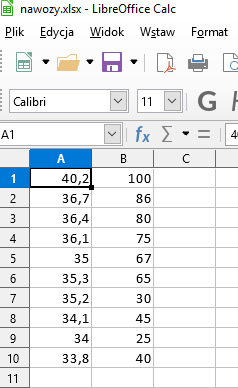

C3 = readcell('nawozy.xlsx')

C3 = 10×2 cell array
    {[40.2000]}    {[100]}
    {[36.7000]}    {[ 86]}
    {[36.4000]}    {[ 80]}
    {[36.1000]}    {[ 75]}
    {[     35]}    {[ 67]}
    {[35.3000]}    {[ 65]}
    {[35.2000]}    {[ 30]}
    {[34.1000]}    {[ 45]}
    {[     34]}    {[ 25]}
    {[33.8000]}    {[ 40]}


Zastosowane funkcje: cell2mat i **corrcoef**


rp3=corrcoef(cell2mat(C3))

rp3 =     1.0000    0.8345
    0.8345    1.0000


rp3(1,2)

ans = 0.8345

0,70≤$\left|r_p \right|$<0,90 – Występuje dość silna zależność między zmiennymi (plony z hektara  x 100 kg a  zużycie nawozów [t]) 0,70≤$\left|r_p \right|$=0,8345 <0,90

k3=size(cell2mat(C3),1)-2 %k3=10-2=8

k3 = 8

p = 0.95;   
alpha=1-p %poziom istotności 0,05

alpha = 0.0500


%statystyka testowa

t3=rp3(1,2)*sqrt((k3)/(1-rp3(1,2)^2))

t3 = 4.2840


pLo = alpha/2

pLo = 0.0250

pUp = 1 - alpha/2

pUp = 0.9750

Zastosowanie funkcji tinv - odwrotnośc dystrybuanty rozkładu t-Studenta

crit3 = tinv([pLo pUp], k3)

crit3 =    -2.3060    2.3060


Zmienna t3=4,2840

ponieważ obszar krytyczny $\left(-\infty ,-2,3060>\cup <2,3060,+\right.$$\infty$) to statystyka testowa t3=4,2840 należy do obszaru krytycznego, istnieje więc przesłanka  do odrzucenia hipotezy  H0 i przyjęcia hipotezy alternatywnej H1 (np. korelacja jest istotna statystycznie).

pt3=2*(1-tcdf(t3,k3))

pt3 = 0.0027

pt3=0,0027$\le$alpha=0,05 (jeżeli p≤α to odrzucamy H0 przyjmując H1).

**Przykład mniejszej liczby przypadków**

C3b = readcell('nawozy.xlsx','Range','A1:B3')

C3b = 3×2 cell array
    {[40.2000]}    {[100]}
    {[36.7000]}    {[ 86]}
    {[36.4000]}    {[ 80]}


rp3b=corrcoef(cell2mat(C3b))

rp3b =     1.0000    0.9747
    0.9747    1.0000


rp3b(1,2)

ans = 0.9747


k3b=size(cell2mat(C3b),1)-2 %k3=10-2=8

k3b = 1

p = 0.95;   
alpha=1-p %poziom istotności 0,05

alpha = 0.0500


%statystyka testowa

t3b=rp3b(1,2)*sqrt((k3b)/(1-rp3b(1,2)^2))

t3b = 4.3576


pLo = alpha/2

pLo = 0.0250

pUp = 1 - alpha/2

pUp = 0.9750

crit3b = tinv([pLo pUp], k3)

crit3b =    -2.3060    2.3060


ponieważ obszar krytyczny $\left(-\infty ,-12,7062>\cup <12,7062,+\right.$$\infty$) to statystyka testowa t3b=4,3576 i nie należy do obszaru krytycznego, nie istnieje więc przesłanka  do odrzucenia hipotezy  H0 (nie istniej korelacja).

Testujemy

- jeżeli p≤α to odrzucamy H0 przyjmując H1

- jeżeli p>α to nie ma podstaw do odrzucenia H0

pt3b=2*(1-tcdf(t3b,k3b))

pt3b = 0.1436

pt3b=0,1436$>$alpha=0,05 (jeżeli p>α to nie ma podstaw do odrzucenia H0).

**Przykład wiiększej liczby zmiennych**

Plik all.xlsx

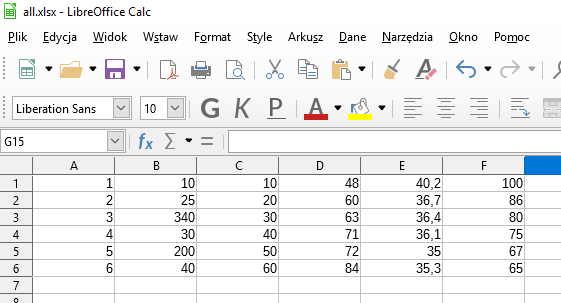

C4 = readcell('all.xlsx','Range','A1:F6')

C4 = 6×6 cell array
    {[1]}    {[ 10]}    {[10]}    {[48]}    {[40.2000]}    {[100]}
    {[2]}    {[ 25]}    {[20]}    {[60]}    {[36.7000]}    {[ 86]}
    {[3]}    {[340]}    {[30]}    {[63]}    {[36.4000]}    {[ 80]}
    {[4]}    {[ 30]}    {[40]}    {[71]}    {[36.1000]}    {[ 75]}
    {[5]}    {[200]}    {[50]}    {[72]}    {[     35]}    {[ 67]}
    {[6]}    {[ 40]}    {[60]}    {[84]}    {[35.3000]}    {[ 65]}


rp4=corrcoef(cell2mat(C4))

rp4 =     1.0000    0.1458    1.0000    0.9755   -0.8541   -0.9734
    0.1458    1.0000    0.1458    0.0615   -0.3413   -0.2582
    1.0000    0.1458    1.0000    0.9755   -0.8541   -0.9734
    0.9755    0.0615    0.9755    1.0000   -0.8736   -0.9599
   -0.8541   -0.3413   -0.8541   -0.8736    1.0000    0.9487
   -0.9734   -0.2582   -0.9734   -0.9599    0.9487    1.0000
